## fIMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')  
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# INVERSE DIFFERENTIAL KINEMATICS: STATICS AND FORCE TRANSFORMATIONS

find the joint velocity vector that realizes a desired end-effector “generalized” velocity (linear and angular) 

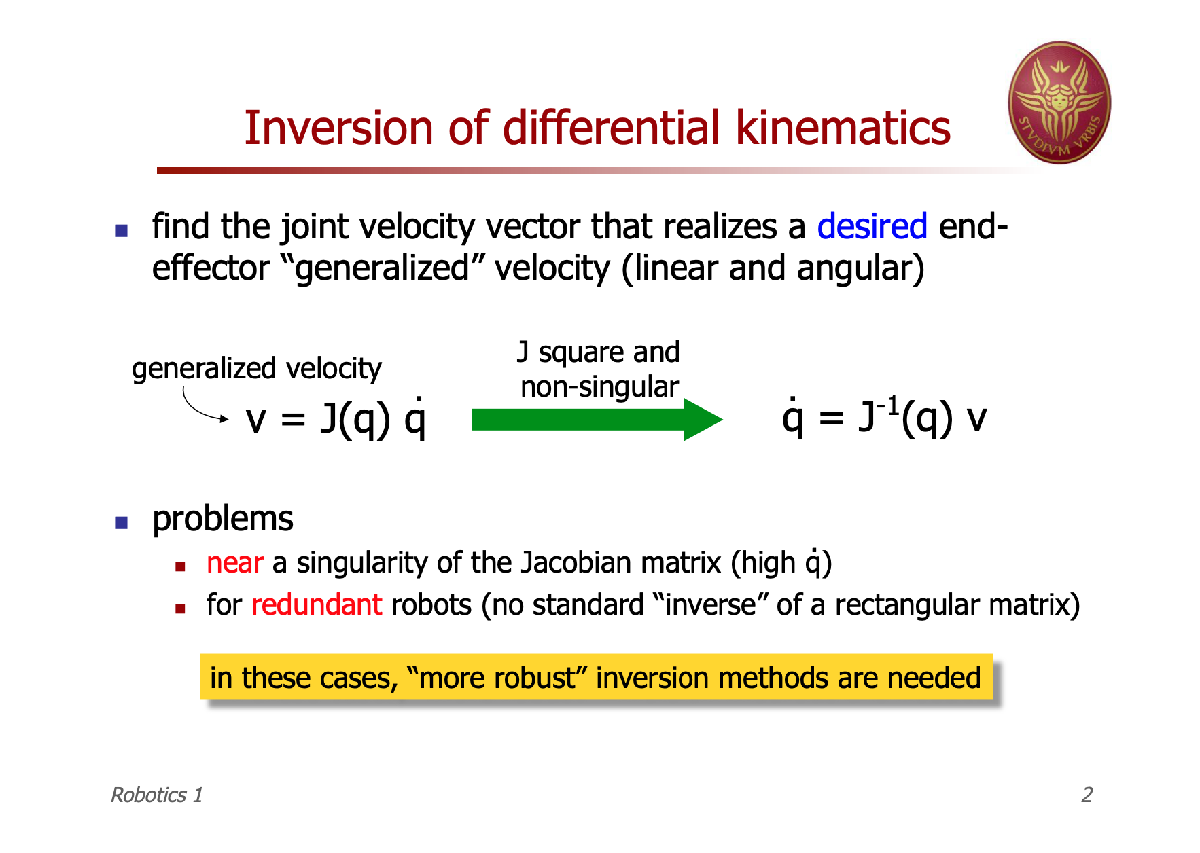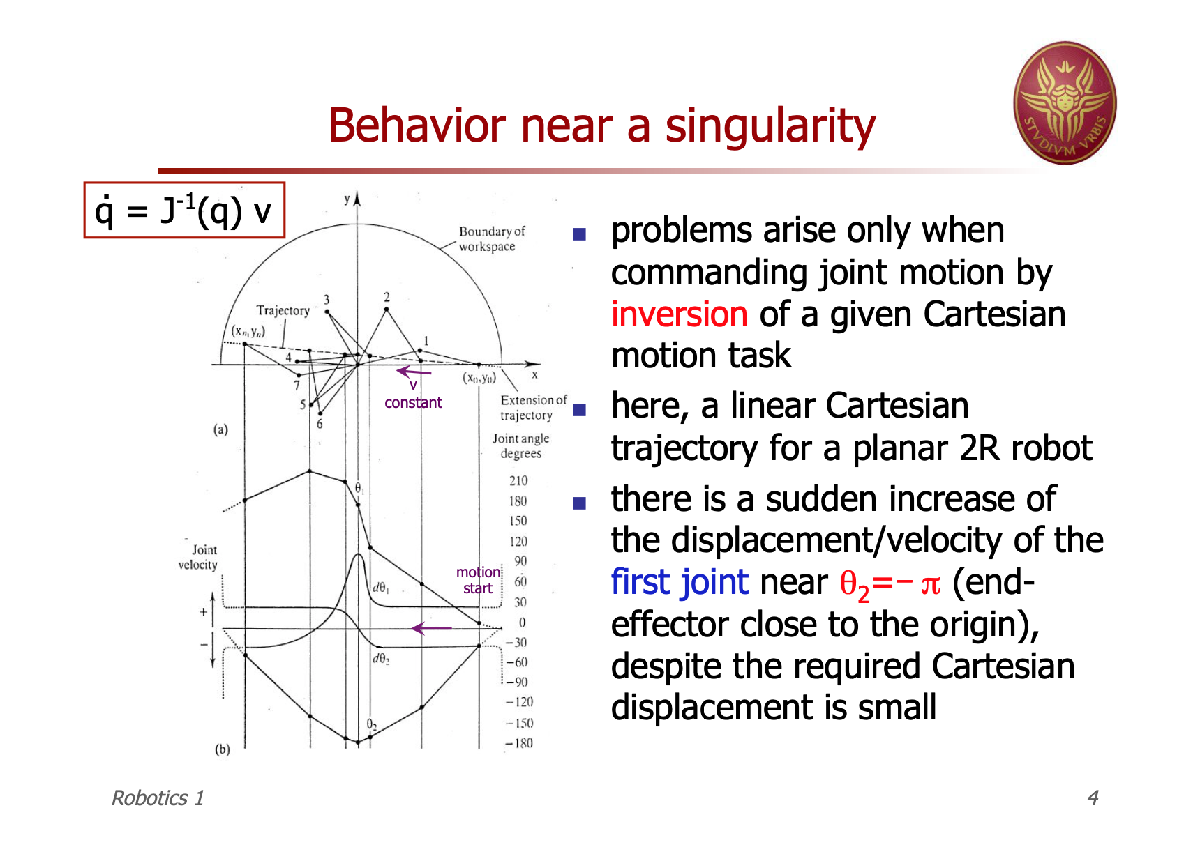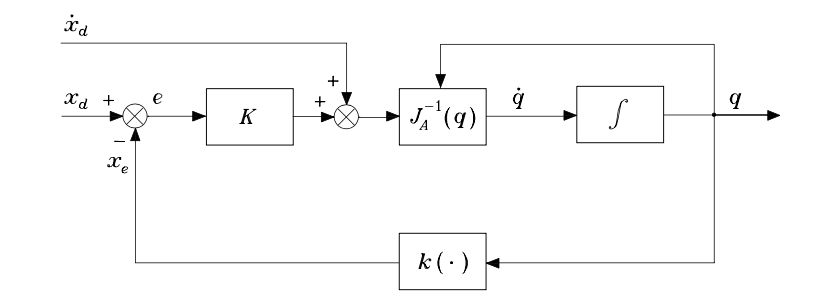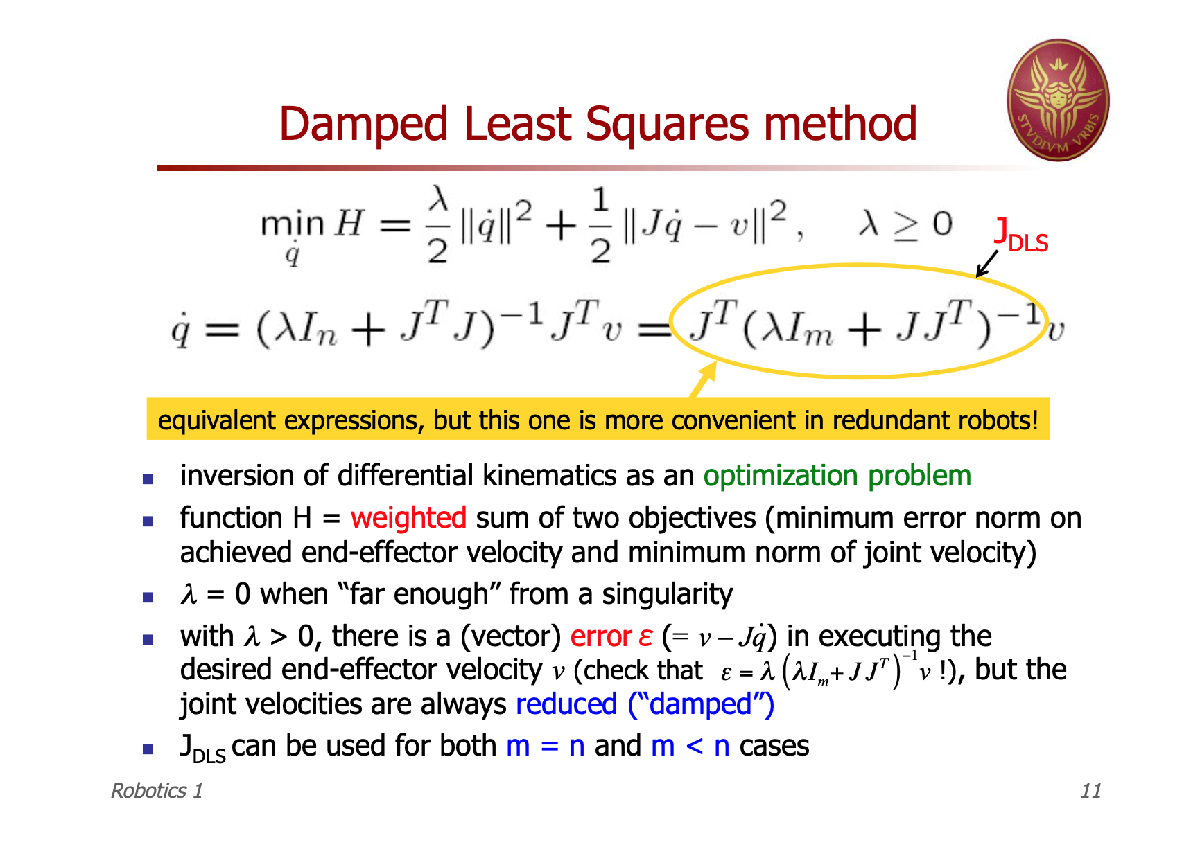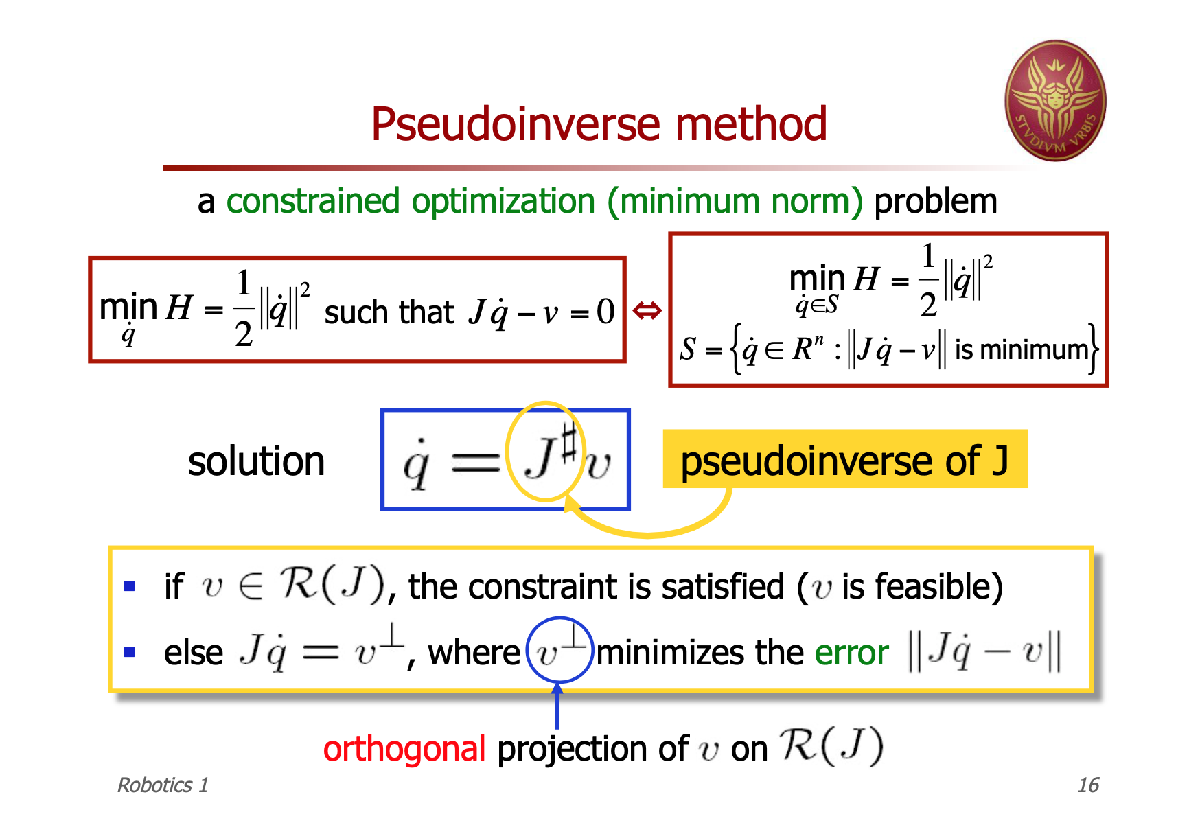

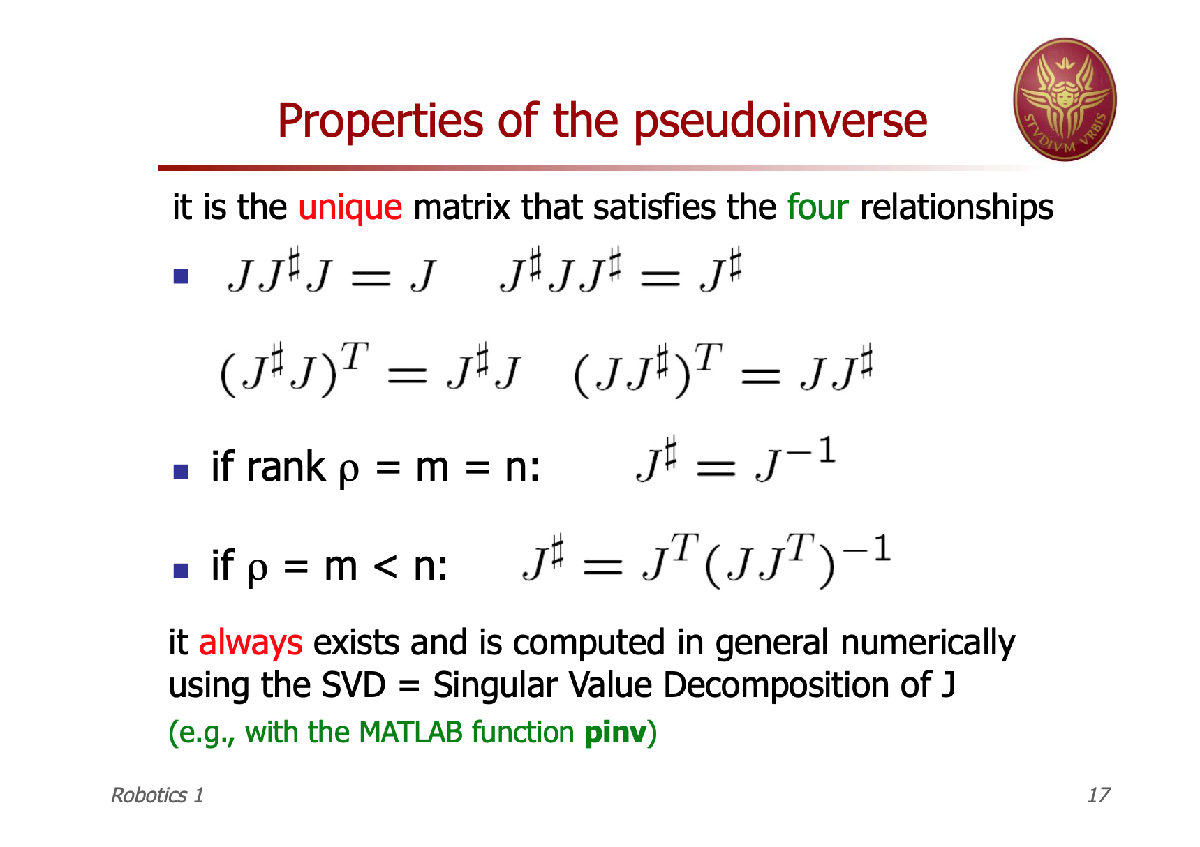

#### PLANAR ARM (2R)

syms alpha1 a1 d1 q1
syms alpha2 a2 d2 q2
warning('off','all')

disp('PLANAR ARM (2R)')

PLANAR ARM (2R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    0   a1  0   q1;
    0   a2  0   q2];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a2'}    {'0'}    {'q2'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% JOINT LIMITS
t1=linspace(-180,180,20)*pi/180;

t2=linspace(-180,180,20)*pi/180;

[t1,t2]=ndgrid(t1,t2);

old = { a1, a2, q1, q2};

new = { 1, 1, t1, t2};

radius = 2;

J_r_sym = simplify(jacobian((T_sym(1:3,4)),[q1 q2]))

$$J\_r\_sym = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$


% TRAJECTORY MODEL
% time in s
time_step=0.01;
start_time=0;
end_time=2;
num_steps=end_time/time_step;
time_vector = time_step * [start_time:num_steps]';

r_d_planar_2R.time = time_vector;
r_d_planar_2R.signals.values = [zeros(size(time_vector)) zeros(size(time_vector))];
r_d_planar_2R.signals.dimensions = 2;
v_d_planar_2R = r_d_planar_2R;

% use dls or inverse jacobian to see differences
[x0, y0] = deal(1.9, 0.001);
[xf, yf] = deal(-1.9, 0.001);
[vx, vy] = deal((xf-x0)/end_time, (yf-y0)/end_time);

for k=1:length(time_vector)
    v_d_planar_2R.signals.values(k,:) = [vx; vy];
    r_d_planar_2R.signals.values(k,:) = [x0+vx*time_vector(k); y0+vy*time_vector(k)];
end

r = [x0 y0]'

r =     1.9000
    0.0010



q = [0 -pi/2]';

F_sym = subs(T_sym,{ a1, a2},{ 1, 1});

F_sym = F_sym(1:length(r),4);

q0_planar_2R = SR_ROBO.newton(F_sym,q,r); % IK - NEWTON

iter : 5 
error : 0.000002 
q_opt : 
    0.3181
   -0.6351



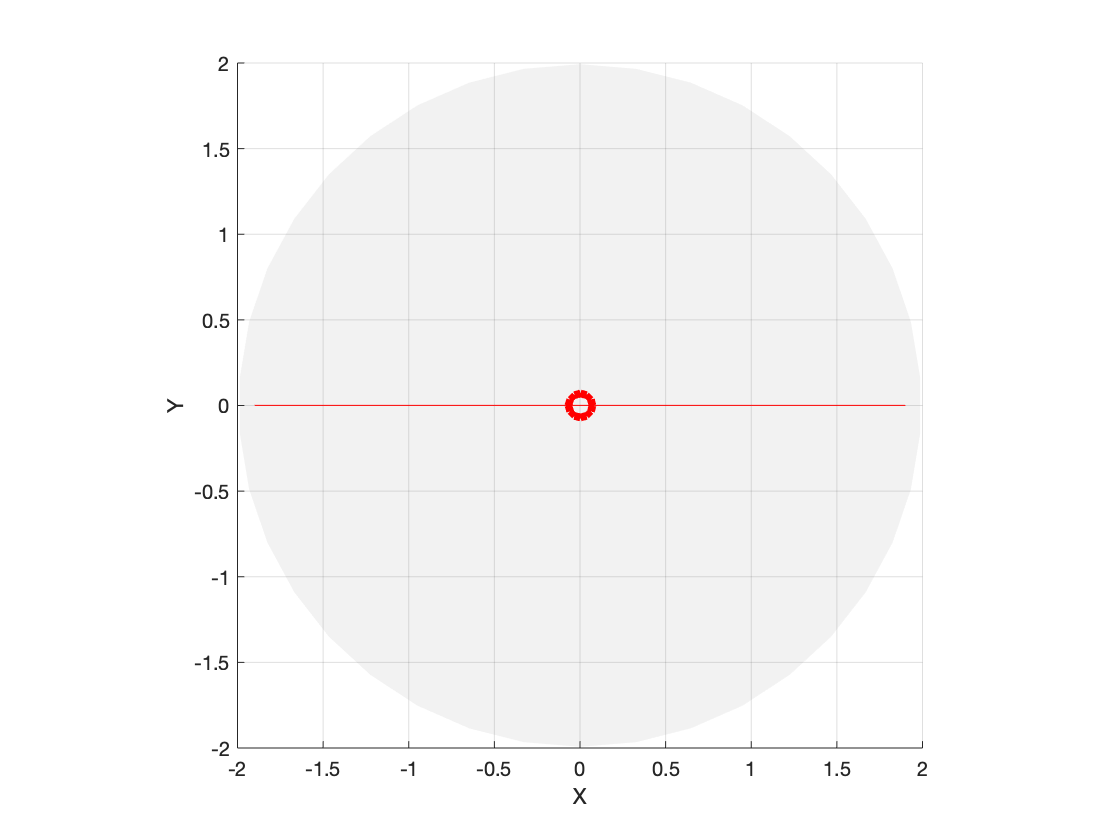


gain_planar_2R = 60;

simOut = sim('PLANAR_2R_IDK',end_time);

clf;

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

view([0 90])

pbaspect([1 1 1])

hold on

% PLOT TRAJECTORY
plot3(r_d_planar_2R.signals.values(:,1),r_d_planar_2R.signals.values(:,2),zeros(length(time_vector),1),'r');

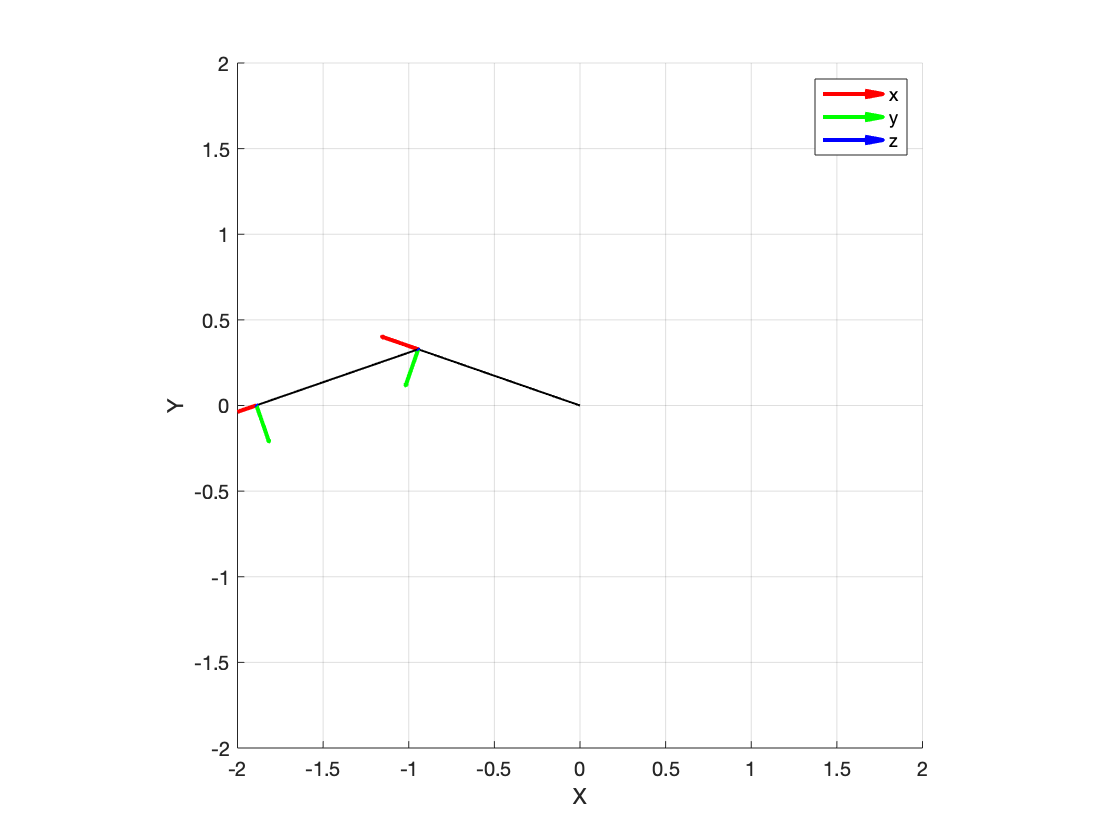



% PLOT RESULT -
for i=1:length(time_vector)
    if mod(i-1,20)==0
        q = simOut.q_planar_2R.Data(i,:);
        
        new_ = { 1, 1, q(1), q(2)};
        
        SR_ROBO.draw_clean(A_list_sym,old,new_,radius,true);
        
        drawnow
    end
end

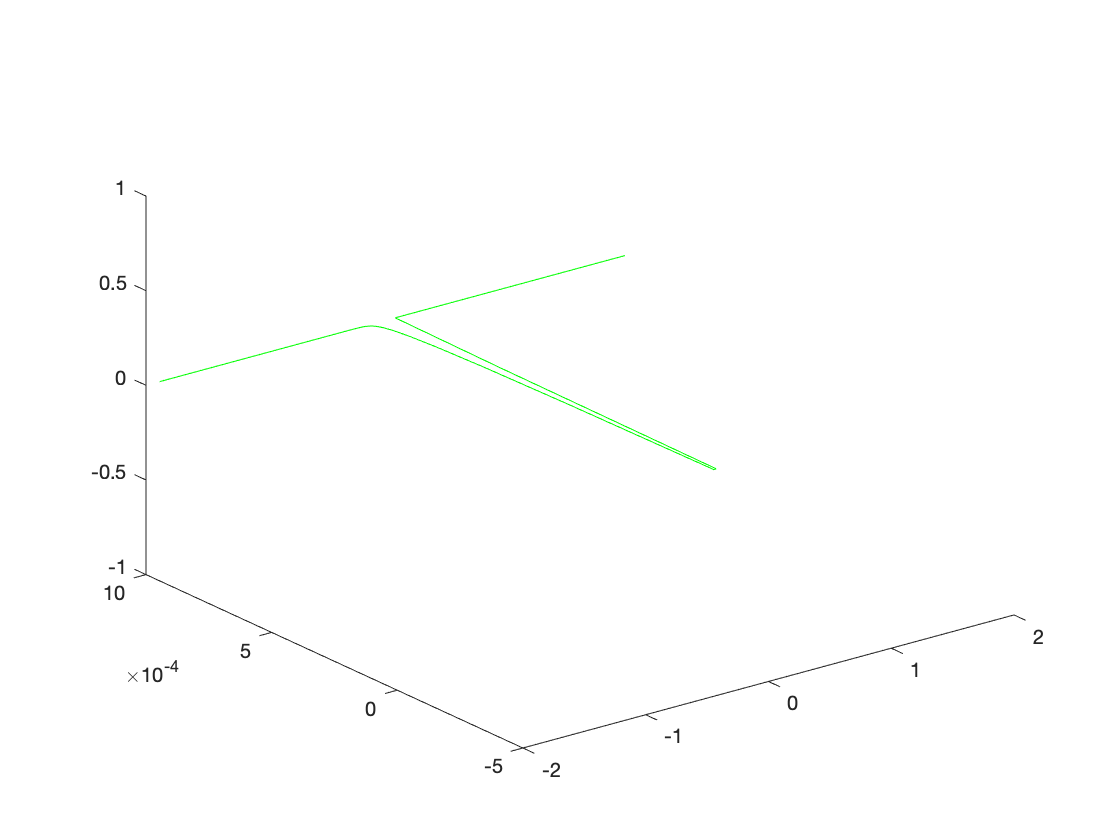


r_out = r_d_planar_2R.signals.values;

% DRAW RESULTING PATH
for i=1:length(time_vector)
    q = simOut.q_planar_2R.Data(i,:);
    r_out(i,:) = double(subs(F_sym,{q1, q2},q)');
end

plot3(r_out(:,1),r_out(:,2),zeros(length(time_vector),1),'g-');

hold off

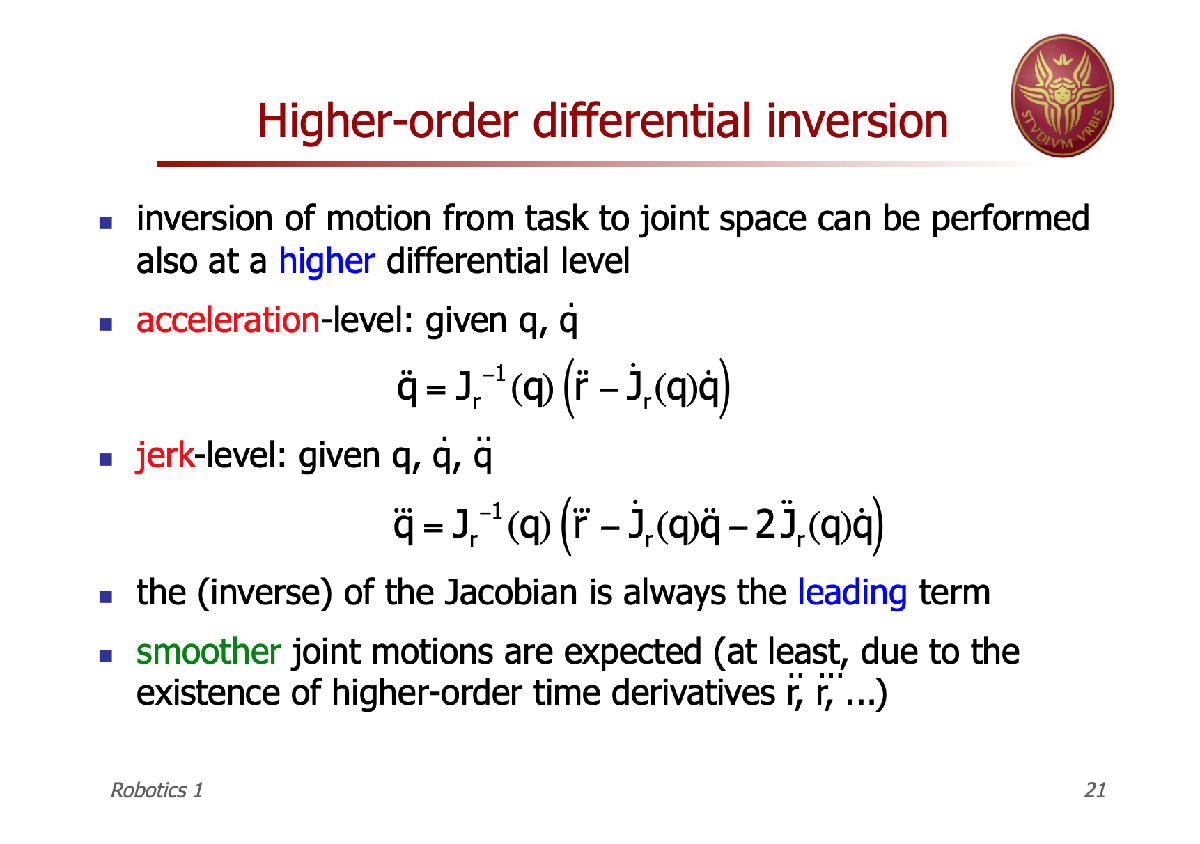

# VELOCITY - FORCE DUALITY

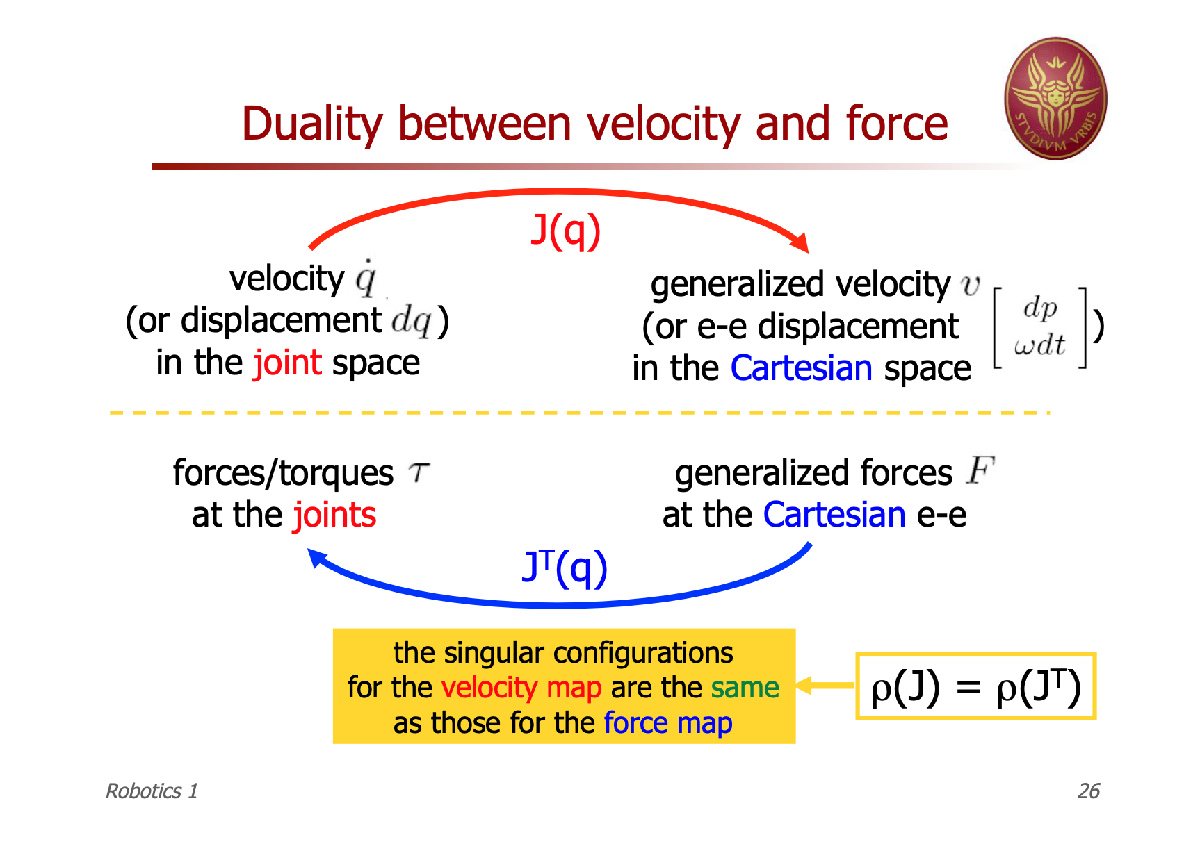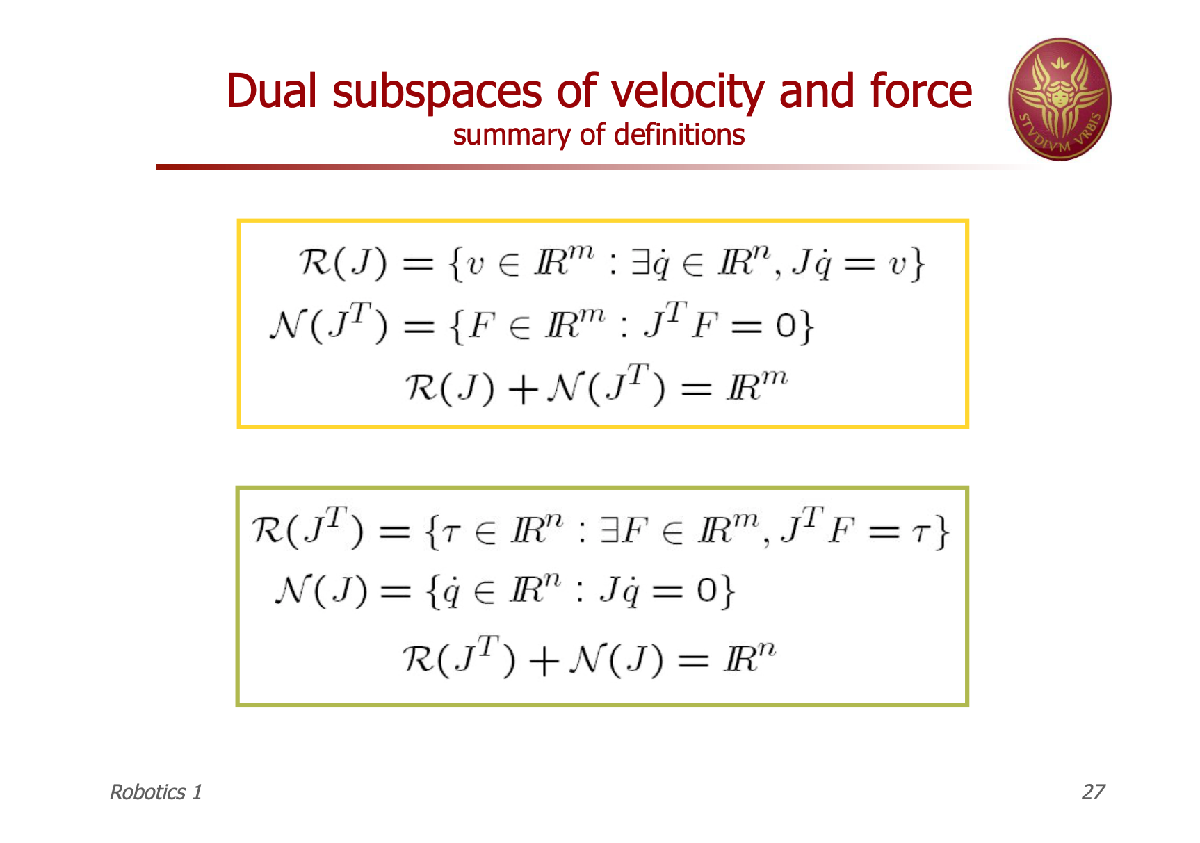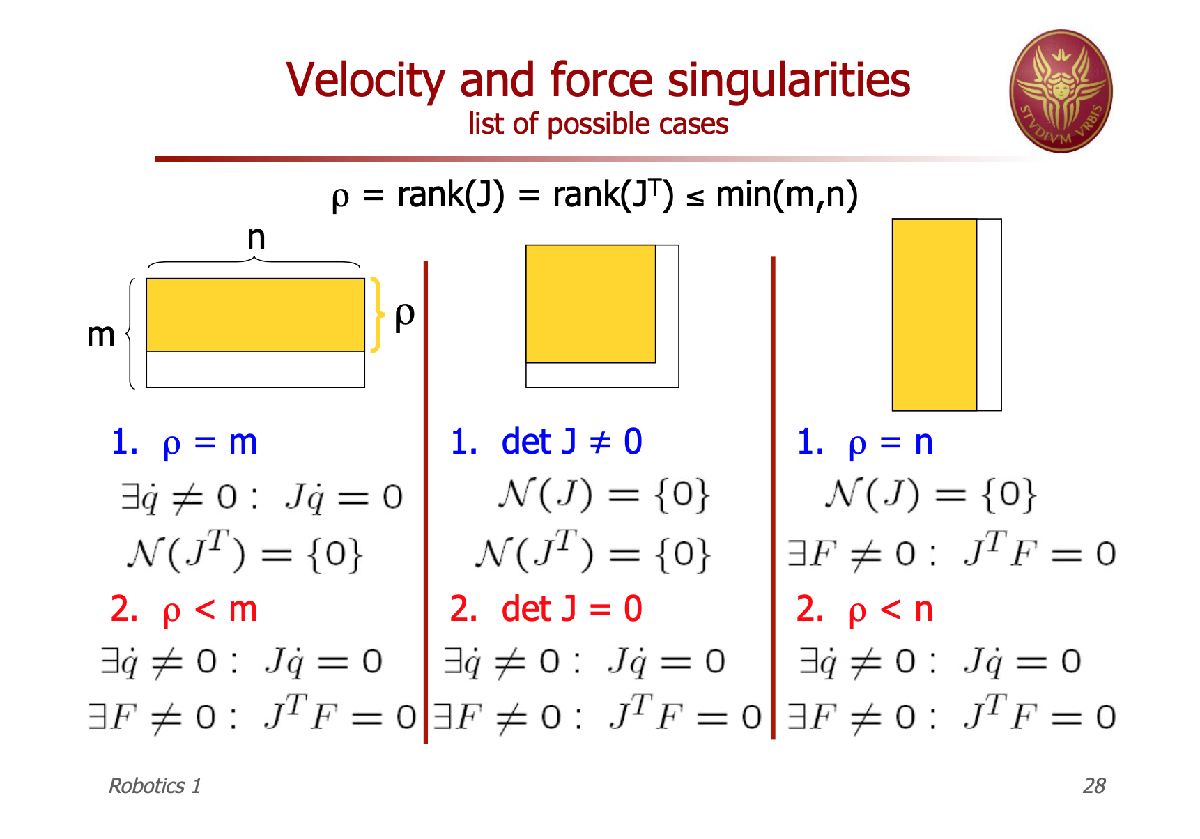

disp('NULL SPACE ANALYSIS PLANAR ARM (2R)')

NULL SPACE ANALYSIS PLANAR ARM (2R)


% ALPHA A   D   THETA
clf;
% DH MODEL
DH_table_ = [ ...
    0   a1  0   q1;
    0   a2  0   q2];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a2'}    {'0'}    {'q2'} 



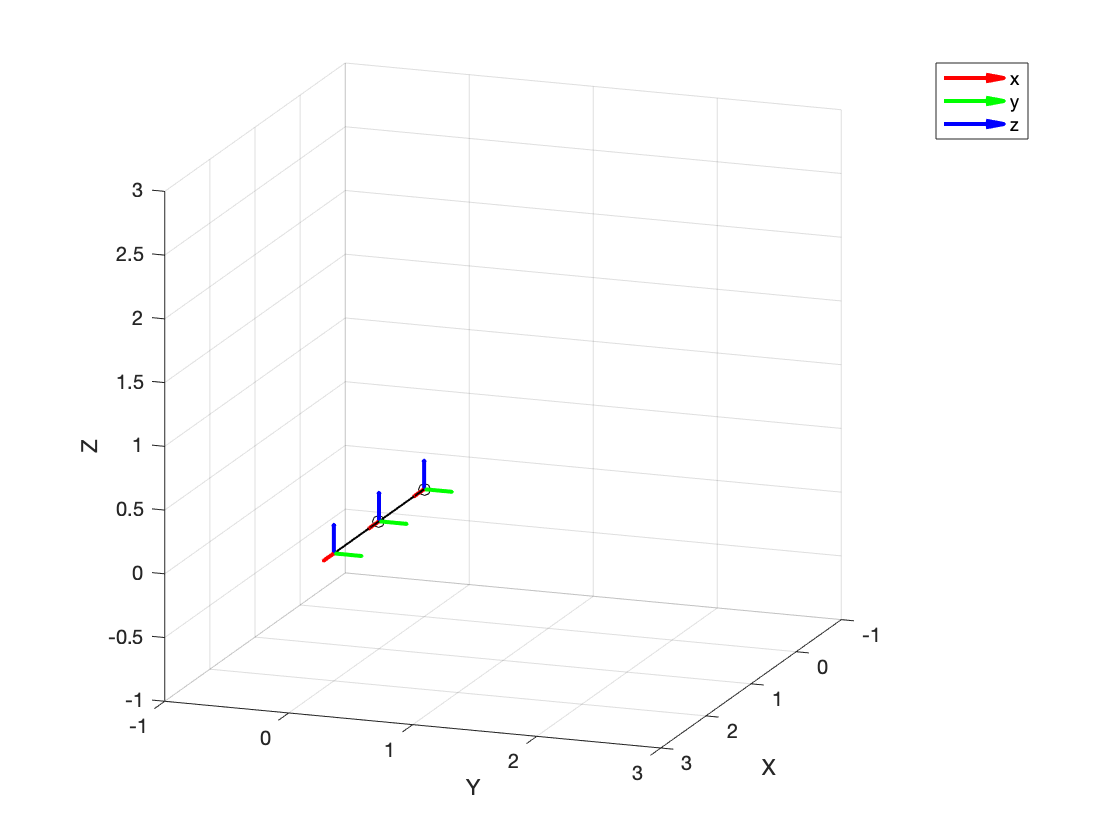


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { q1, q2};

new_draw_joint = {1, 1};

new = {0, 0}; % singular configuration, try {pi/2, pi/4, -pi/2} instead

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},{ a1, a2, q1, q2},[new_draw_joint new]));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);


F_sym = T_sym(1:3,4) % p

$$F\_sym = \left(\begin{array}{c} a_{1}\,\cos\left(q_{1}\right)+a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-a_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ a_{1}\,\sin\left(q_{1}\right)+a_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$


J = simplify(jacobian(F_sym,[q1 q2]))

$$J = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$


J = subs(J,old,new)

$$J = \left(\begin{array}{cc} 0 & 0\\ a_{1}+a_{2} & a_{2}\\ 0 & 0 \end{array}\right)$$


disp('n = joint space')

n = joint space


disp('m = task space')

m = task space



disp(['RANK(J) = DIRECTIONS OF NON ZERO CARTESIAN VELOCITIES ' ...
    'IN A GIVEN CONFIGURATION'])

RANK(J) = DIRECTIONS OF NON ZERO CARTESIAN VELOCITIES IN A GIVEN CONFIGURATION



rank_J = rank(J)

rank_J = 1


disp(['NULL(J) = DIRECTIONS OF ZERO CARTESIAN VELOCITIES ' ...
    '(FOR q ~= 0)  IN A GIVEN CONFIGURATION'])

NULL(J) = DIRECTIONS OF ZERO CARTESIAN VELOCITIES (FOR q ~= 0)  IN A GIVEN CONFIGURATION



nullspace_J = null(J)

$$nullspace\_J = \left(\begin{array}{c} -\frac{a_{2}}{a_{1}+a_{2}}\\ 1 \end{array}\right)$$


null_J = size(nullspace_J,2)

null_J = 1


JT = J'

$$JT = \left(\begin{array}{ccc} 0 & \bar{a_{1}}+\bar{a_{2}} & 0\\ 0 & \bar{a_{2}} & 0 \end{array}\right)$$


disp(['RANK(JT) = FORCE DIRECTIONS THAT PRODUCES NON ZERO JOINT TORQUES' ...
    '  IN A GIVEN CONFIGURATION'])

RANK(JT) = FORCE DIRECTIONS THAT PRODUCES NON ZERO JOINT TORQUES  IN A GIVEN CONFIGURATION



rank_JT = rank(JT)

rank_JT = 1


disp(['NULL(JT) = FORCE DIRECTIONS THAT PRODUCES ZERO JOINT TORQUES ' ...
    '(FOR F ~= 0)  IN A GIVEN CONFIGURATION'])

NULL(JT) = FORCE DIRECTIONS THAT PRODUCES ZERO JOINT TORQUES (FOR F ~= 0)  IN A GIVEN CONFIGURATION



nullspace_JT = null(JT)

$$nullspace\_JT = \left(\begin{array}{cc} 1 & 0\\ 0 & 0\\ 0 & 1 \end{array}\right)$$


null_JT = size(nullspace_JT,2)

null_JT = 2


disp('Rn = RANK(JT) + NULL(J)')

Rn = RANK(JT) + NULL(J)



R_n = rank_JT + null_J

R_n = 2


disp('Rm = RANK(J) + NULL(JT)')

Rm = RANK(J) + NULL(JT)



R_m = rank_J + null_JT

R_m = 3

# VELOCITY MANIPULABILITY

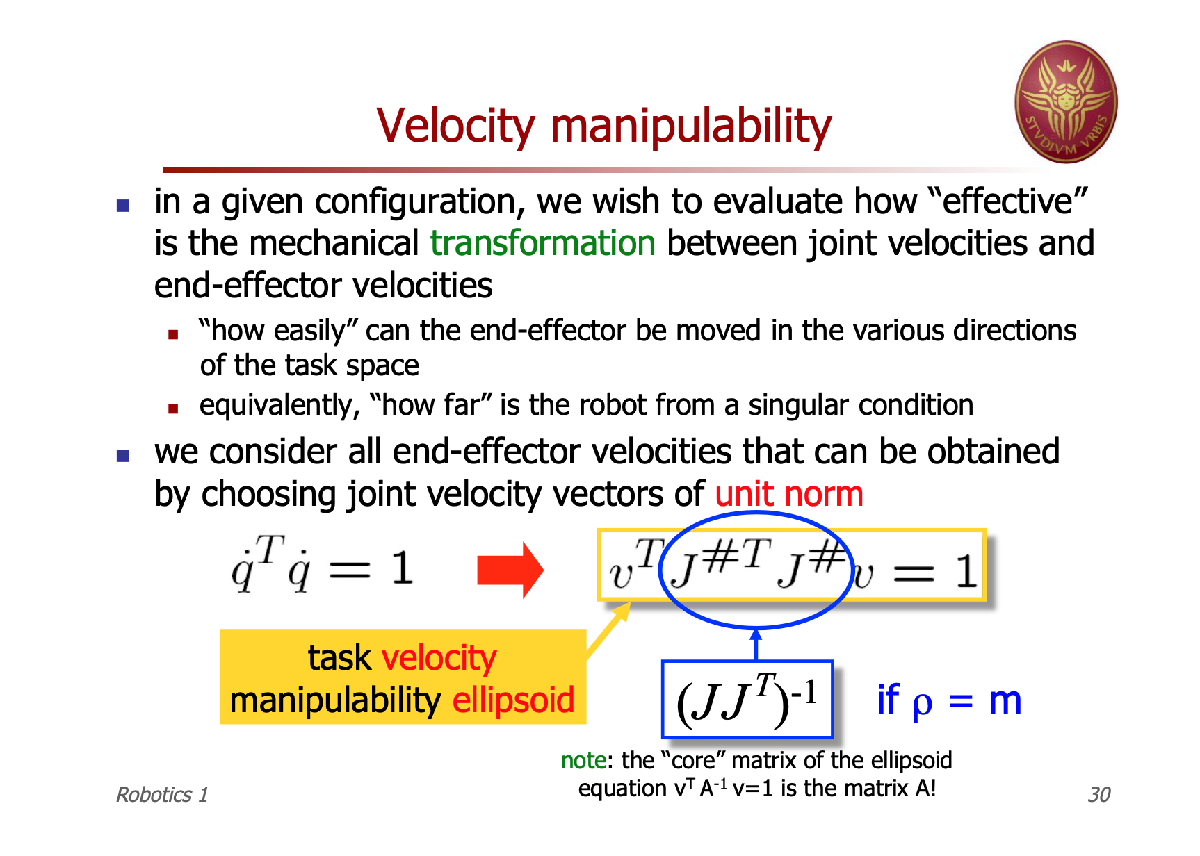

#### PLANAR ARM (2R)

syms alpha1 a1 d1 q1
syms alpha2 a2 d2 q2
warning('off','all')

disp('PLANAR ARM (2R)')

PLANAR ARM (2R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    0   a1  0   q1;
    0   a2  0   q2];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a2'}    {'0'}    {'q2'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% JOINT LIMITS
t1=linspace(-180,180,20)*pi/180;

t2=linspace(-180,180,20)*pi/180;

[t1,t2]=ndgrid(t1,t2);

old = { a1, a2, q1, q2};

new = { 1, 1, t1, t2};

radius = 2;

J_r_sym = simplify(jacobian((T_sym(1:3,4)),[q1 q2]))

$$J\_r\_sym = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$


% TRAJECTORY MODEL
% time in s
time_step=0.01;
start_time=0;
end_time=1;
num_steps=end_time/time_step;
time_vector = time_step * [start_time:num_steps]';

r_d_planar_2R.time = time_vector;
r_d_planar_2R.signals.values = [zeros(size(time_vector)) zeros(size(time_vector))];
r_d_planar_2R.signals.dimensions = 2;
v_d_planar_2R = r_d_planar_2R;

% use dls or inverse jacobian to see differences
[x0, y0] = deal(2, 0);
[xf, yf] = deal(0, 0);
[vx, vy] = deal((xf-x0)/end_time, (yf-y0)/end_time);

for k=1:length(time_vector)
    v_d_planar_2R.signals.values(k,:) = [vx; vy];
    r_d_planar_2R.signals.values(k,:) = [x0+vx*time_vector(k); y0+vy*time_vector(k)];
end

r = [x0 y0]'

r =      2
     0



q = [0 -pi/2]';

F_sym = subs(T_sym,{ a1, a2},{ 1, 1});

F_sym = F_sym(1:length(r),4)

$$F\_sym = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right)+\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}\right)$$


q0_planar_2R = SR_ROBO.newton(F_sym,q,r); % IK - NEWTON

iter : 8 
error : 0.000042 
q_opt : 
    0.0032
   -0.0065




gain_planar_2R = 60;

simOut = sim('PLANAR_2R_IDK',end_time);

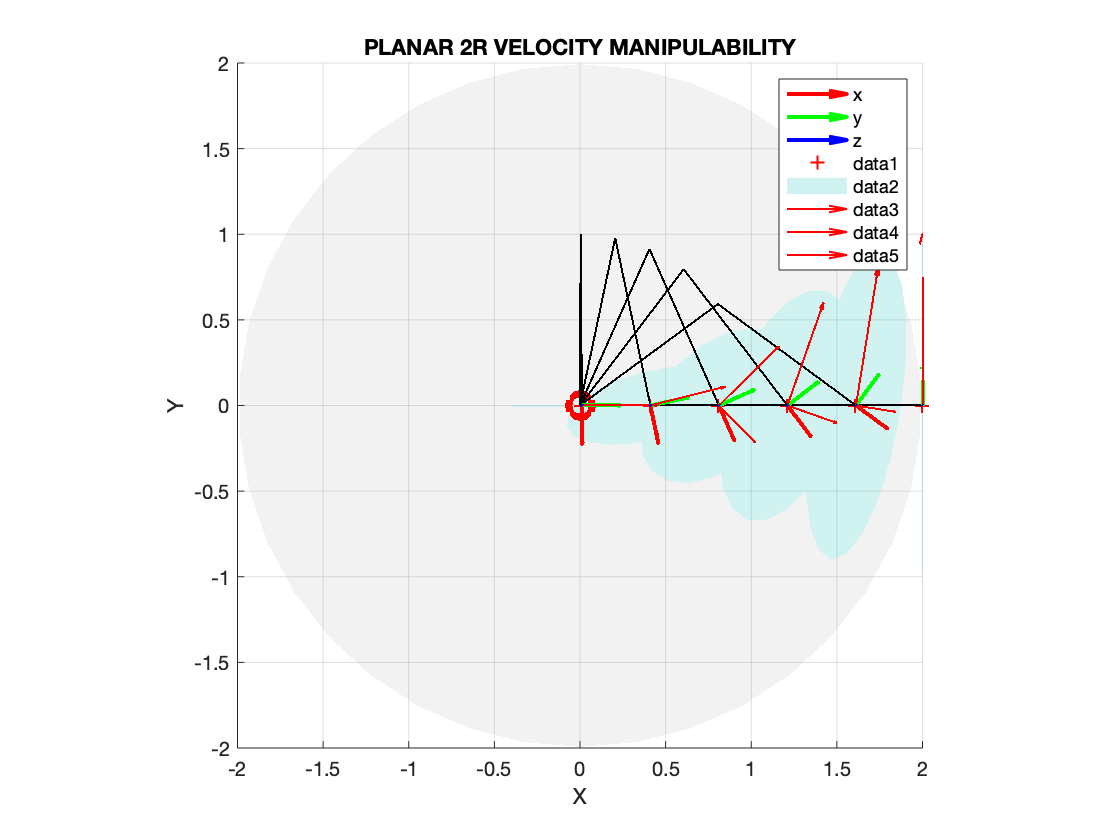


clf;

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

view([0 90])

pbaspect([1 1 1])

title('PLANAR 2R VELOCITY MANIPULABILITY')

hold on

% PLOT TRAJECTORY
plot3(r_d_planar_2R.signals.values(:,1),r_d_planar_2R.signals.values(:,2),zeros(length(time_vector),1),'r');

% PLOT RESULT
for i=1:length(time_vector)
    if mod(i-1,20)==0
        q = simOut.q_planar_2R.Data(i,:);
        
        new_ = { 1, 1, q(1), q(2)};
        
        SR_ROBO.draw_clean(A_list_sym,old,new_,radius,false);
        
        hold on
        
        r = double(subs(F_sym,{q1, q2},q));
        
        J_r = subs(J_r_sym,old,new_);
        
        A = J_r*J_r';
        
        SR_ROBO.draw_manipulability_ellipsoid(A,r);
        
        drawnow
    end
end

hold off


manip_measure = time_vector;

for i=1:length(time_vector)
    q = simOut.q_planar_2R.Data(i,:);
    
    new_ = { 1, 1, q(1), q(2)};
        
    J_r = double(subs(J_r_sym(1:2,:),old,new_));
    
    manip_measure(i)=sqrt(det(J_r*J_r'));
end

figure

hold on

plot(r_d_planar_2R.signals.values(:,1),manip_measure(:));

[best_manipulability, best_index] = max(manip_measure);

best_manipulability

best_manipulability = 1.0000


best_distance = r_d_planar_2R.signals.values(best_index,1)

best_distance = 1.4000

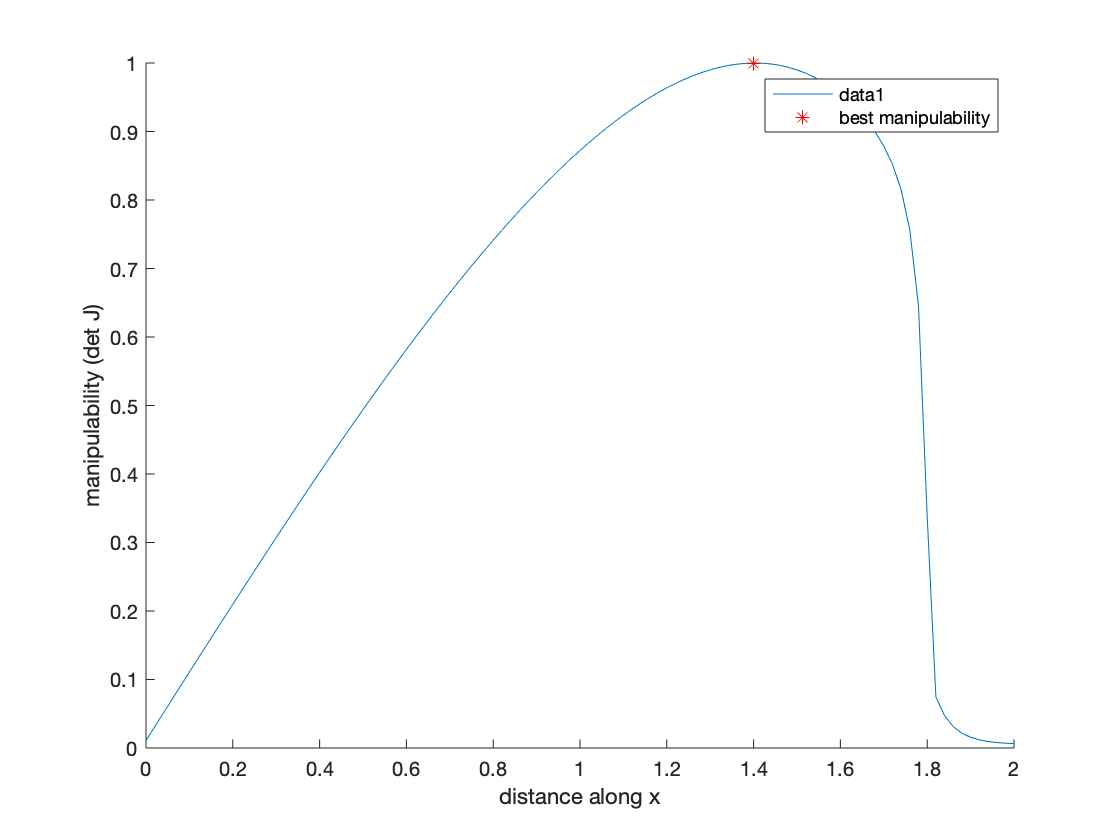


plot(best_distance,best_manipulability,'r*','DisplayName','best manipulability');

xlabel('distance along x')

ylabel('manipulability (det J)')

legend 

hold off

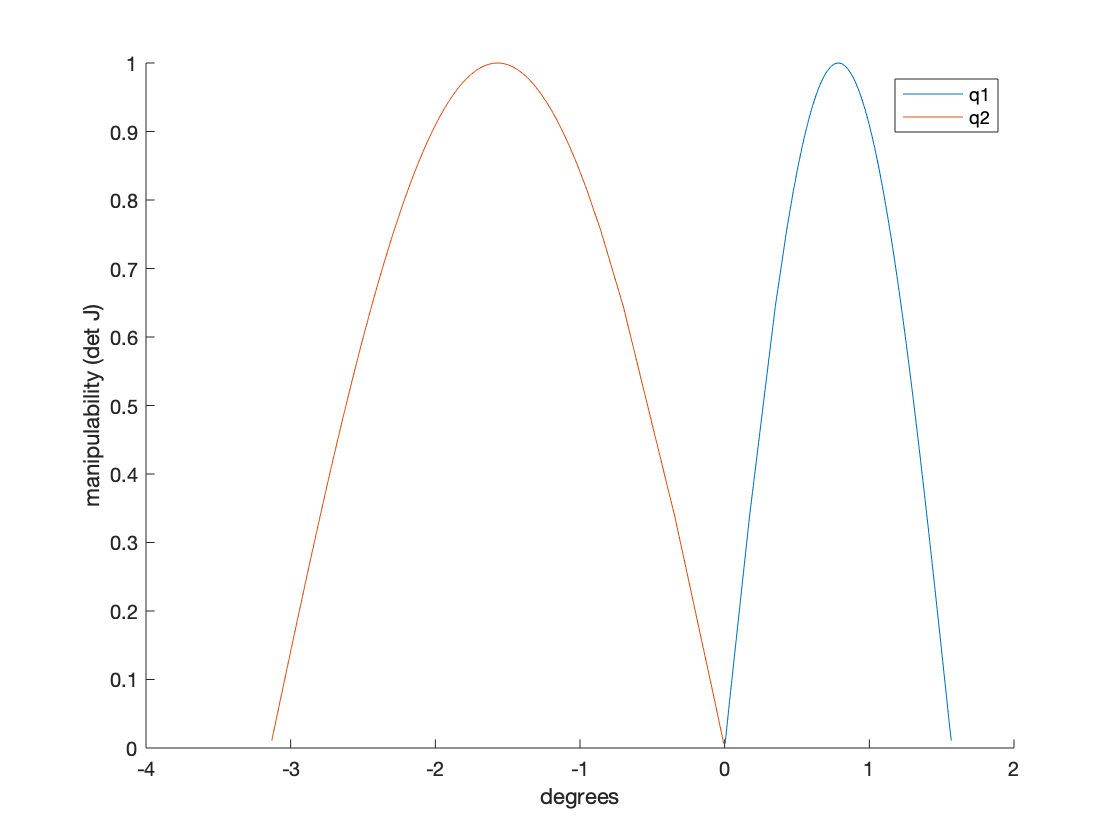


figure

hold on

plot(simOut.q_planar_2R.Data(:,1),manip_measure(:));

plot(simOut.q_planar_2R.Data(:,2),manip_measure(:));

legend('q1','q2')

xlabel('degrees')

ylabel('manipulability (det J)')

hold off

# FORCE MANIPULABILITY

# 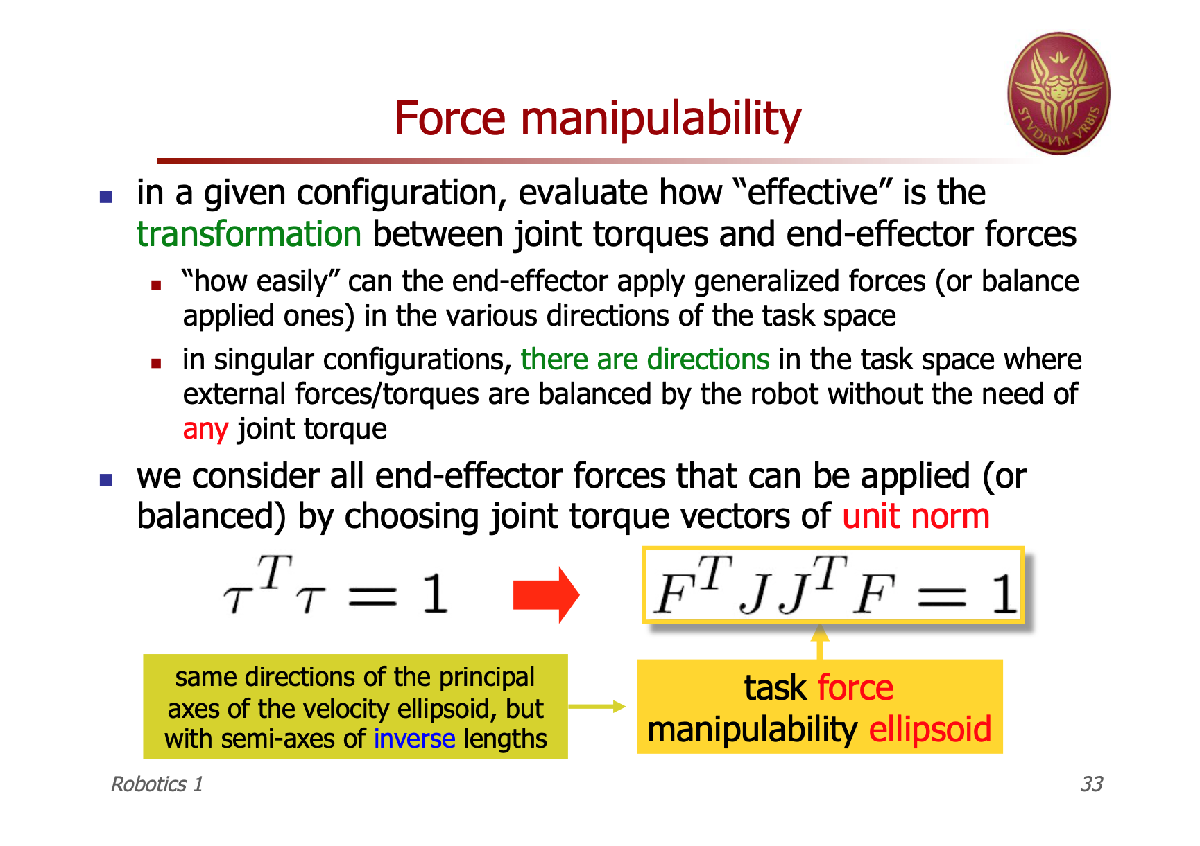

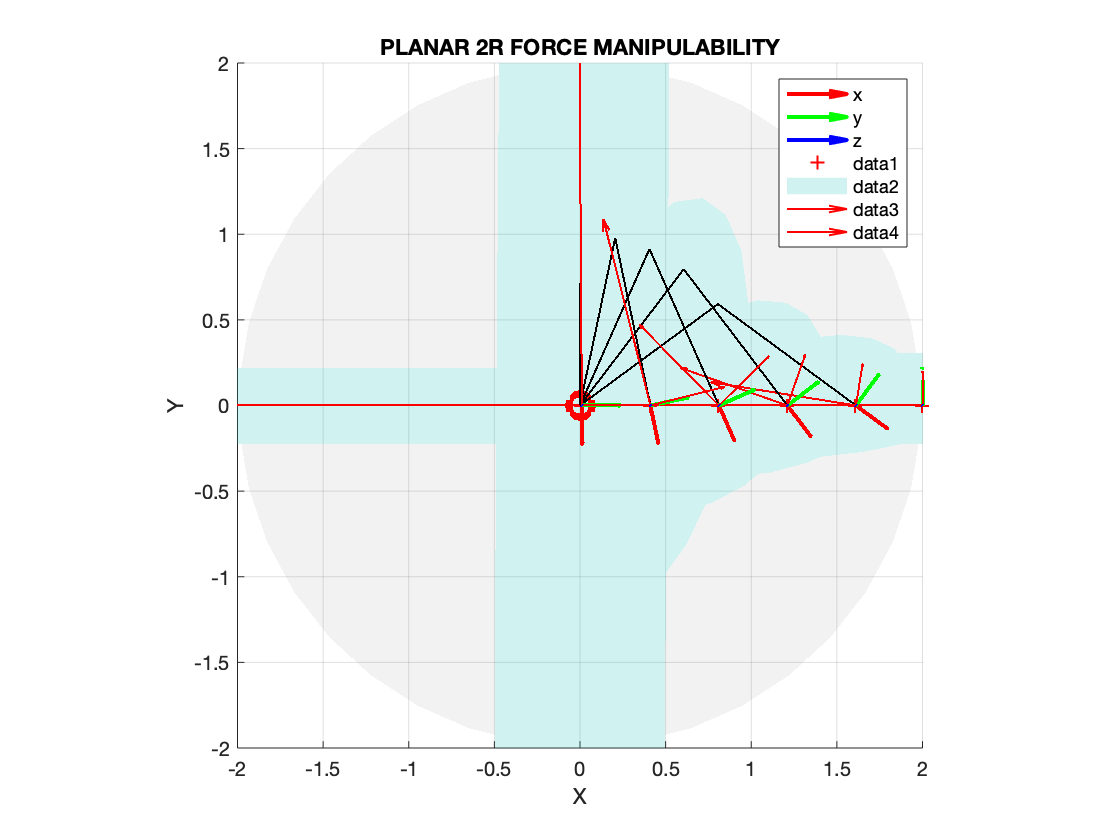

clf;

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

view([0 90])

pbaspect([1 1 1])

title('PLANAR 2R FORCE MANIPULABILITY')

hold on

% PLOT TRAJECTORY
plot3(r_d_planar_2R.signals.values(:,1),r_d_planar_2R.signals.values(:,2),zeros(length(time_vector),1),'r');

% PLOT RESULT
for i=1:length(time_vector)
    if mod(i-1,20)==0
        q = simOut.q_planar_2R.Data(i,:);
        
        new_ = { 1, 1, q(1), q(2)};
        
        SR_ROBO.draw_clean(A_list_sym,old,new_,radius,false);
        
        hold on 
        
        r = double(subs(F_sym,{q1, q2},q));
        
        J_r = double(subs(J_r_sym(1:2,:),old,new_));
        
        A = inv(J_r*J_r');
        
        SR_ROBO.draw_manipulability_ellipsoid(A,r);
        
        drawnow
    end
end

hold off

# VELOCITY AND FORCE CHANGING REFERENCE FRAME

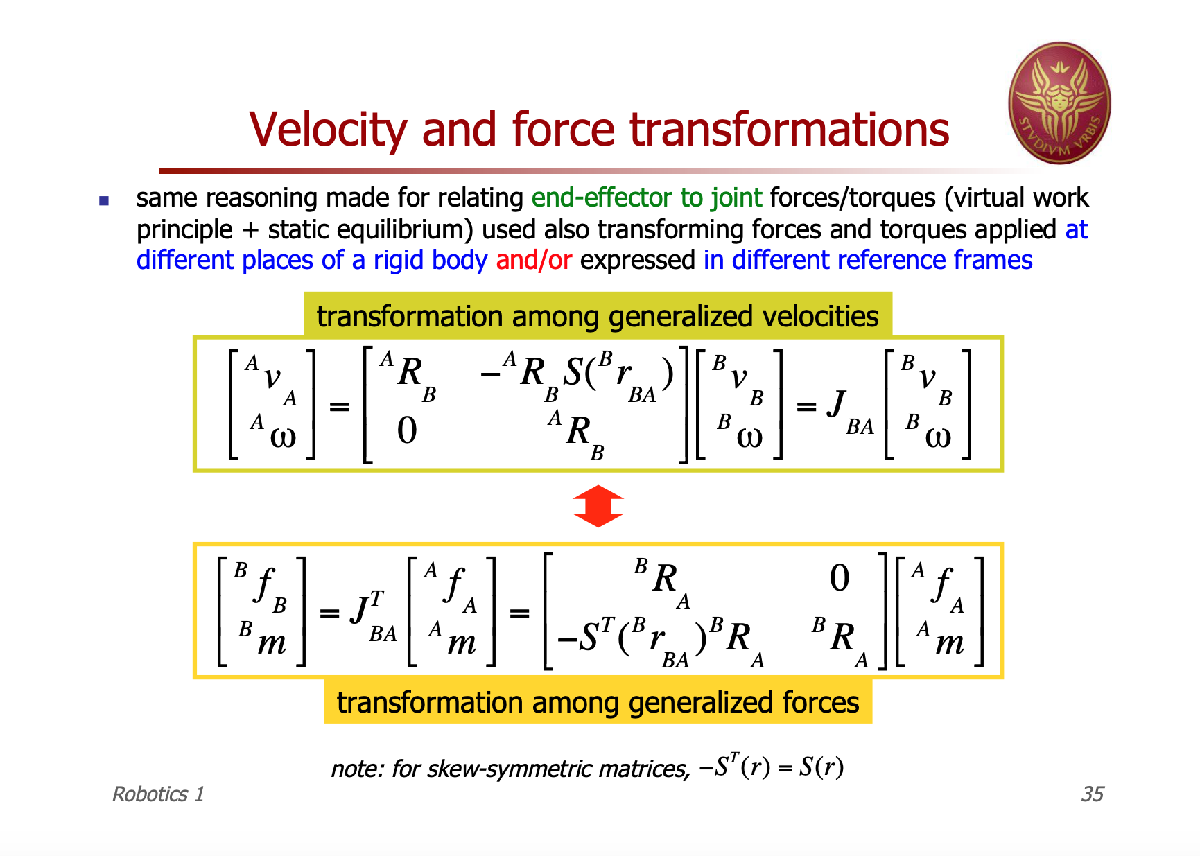

#### VELOCITY

vB = sym('vB',[3 1]);

wB = sym('wB',[3 1]);

% assume whatever reference frame RB_0
RA_B = [1 0 0; 
        0 1 0;
        0 0 1];
% determinant of the jacobian not depends by the reference frame
% compute rA_B
rB_A = [0 0 0]'

rB_A =      0
     0
     0



S_A_B = SR_ROBO.skew(rB_A(1),rB_A(2),rB_A(3))

S_A_B =      0     0     0
     0     0     0
     0     0     0



% -S_A_B because w_b x r_ab = - r_ab x w_b ==> v_a = v_b - r_ab x w_b 
J_B_A = [RA_B -RA_B*S_A_B; zeros(3,3) RA_B]

J_B_A =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



VA = J_B_A * [vB; wB];

[vA, wA] = deal(VA(1:3,:),VA(4:6,:))

$$vA = \left(\begin{array}{c} {\mathrm{vB}}_{1}\\ {\mathrm{vB}}_{2}\\ {\mathrm{vB}}_{3} \end{array}\right)$$

$$wA = \left(\begin{array}{c} {\mathrm{wB}}_{1}\\ {\mathrm{wB}}_{2}\\ {\mathrm{wB}}_{3} \end{array}\right)$$

#### FORCE (dual)

fA = sym('fA',[3 1]);

mA = sym('mA',[3 1]);

FB = J_B_A' * [fA; mA];

[fB, mB] = deal(FB(1:3,:),FB(4:6,:))

$$fB = \left(\begin{array}{c} {\mathrm{fA}}_{1}\\ {\mathrm{fA}}_{2}\\ {\mathrm{fA}}_{3} \end{array}\right)$$

$$mB = \left(\begin{array}{c} {\mathrm{mA}}_{1}\\ {\mathrm{mA}}_{2}\\ {\mathrm{mA}}_{3} \end{array}\right)$$